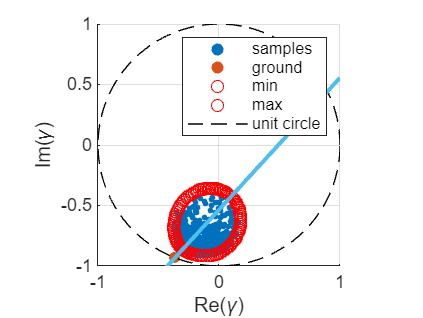

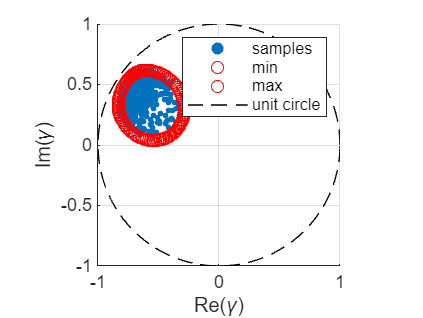

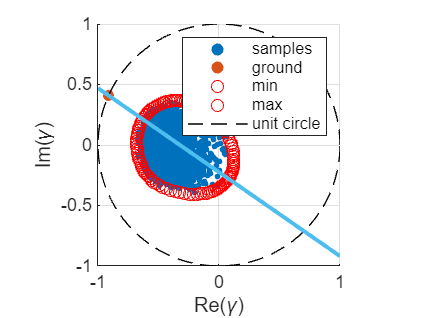

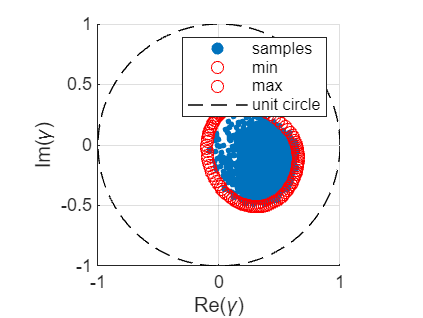

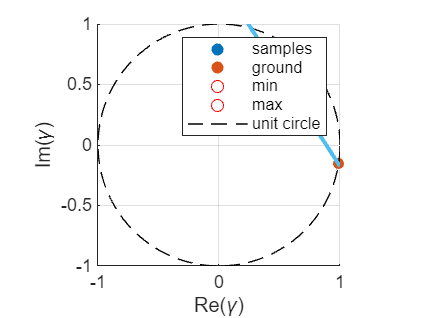

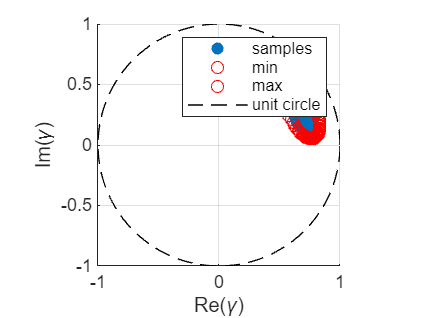

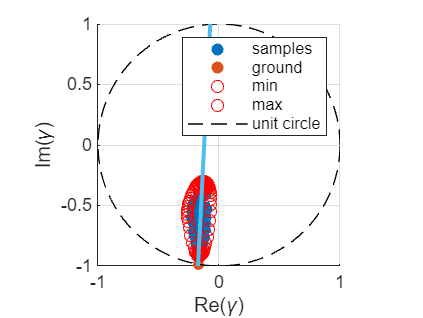

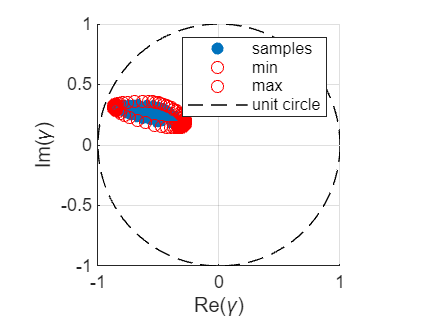

clear;

fileNames = ["data/c3x7_s1602_l48.m","data/c3x7_s1794_l290.m","data/c3x7_s1914_l275.m","data/c7x17_s1602_l48.m","data/c7x17_s1794_l290.m","data/c7x17_s1914_l275.m"];
P_values = zeros(6, 2);
for l=1:6
boundary_N = 60;
fileName = fileNames(l);
N = 2000;
Samples = BruteForce(fileName, N);
CoherencePoints = PauliBasesPoints(fileName);
boundary_vals = BoundaryScan(fileName, boundary_N);
temp = [boundary_vals(:, 1);boundary_vals(:, 2)];
P = linortfit(real(temp), imag(temp));
P_values(l, :) = P;

groundPoint = findGround(P, CoherencePoints);

% --- Plot the brute-force sampled points ---
figure('Name','Coherence points','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
scatter(real(Samples), imag(Samples), 8, 'filled');
scatter(real(groundPoint(1)), groundPoint(2), 30, 'filled');
scatter(real(boundary_vals(:,1)), imag(boundary_vals(:,1)), 'ro', 'red');
scatter(real(boundary_vals(:,2)), imag(boundary_vals(:,2)), 'ro', 'red');

% draw unit circle for reference
th = linspace(0,2*pi,500);
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
x = linspace(-1, 1, 100);
plot(x,P(1)+P(2)*x, 'LineWidth', 2);
% labels and title
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');
xlim([-1 1]);
ylim([-1 1]);

% legend
legend('samples', 'ground','min','max', 'unit circle');

hold off;  % optional, release hold
figure('Name','Coherence points','NumberTitle','off');
hold on;  % keep all plots in the same figure
axis equal; grid on;

% scatter plot of your samples
rot=j*angle(groundPoint(1)+j*groundPoint(2));
samplerot=Samples*exp(rot);
boundary_rot=boundary_vals*exp(rot);
scatter(real(samplerot), imag(samplerot), 8, 'filled');
scatter(real(boundary_rot(:,1)), imag(boundary_rot(:,1)), 'ro', 'red');
scatter(real(boundary_rot(:,2)), imag(boundary_rot(:,2)), 'ro', 'red');
plot(cos(th), sin(th), 'k--', 'LineWidth', 0.7);
xlabel('Re(\gamma)'); 
ylabel('Im(\gamma)');
xlim([-1 1]);
ylim([-1 1]);

% legend
legend('samples','min','max', 'unit circle');
end

writematrix(P_values, "Boundary_OR_Values");
